## Spherical Cap

**Disclaimer: The below material was produced in order to serve as a guide for how to approach similar Questions. It is not meant to support or enable plagiarism in any way shape or form. **

Archimedes principle states that the upward boyancy force applied to an object submerged in a fluid, is equal to the weight of the fluid displaced. 

The object can be submerged partially or completely. 

In the context of this document, h is the height of the object (sphere) above the liquid's surface. 

Source: [https://en.wikipedia.org/wiki/Archimedes%27_principle](https://en.wikipedia.org/wiki/Archimedes%27_principle) 

**Equations: **

The below equations are originally from the provided coursework, from the University of ...

- The spherical cap volume of heigh h is:

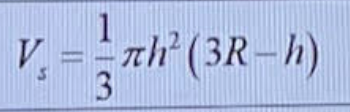 [1]

- The buoyance force is:

 [2]

- The difference betweent he buoyancy force F_g and the sphere weight F_g is:

 [3]

- The portion of the float that is submerged is obtained when the mass of the float equates the mass of the water that is displaced, this equation given by:

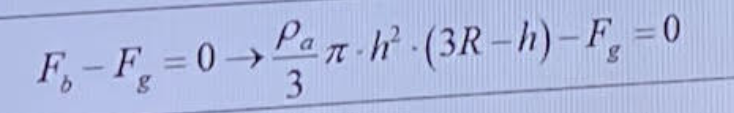 [4]

Solve for h in [4]. 

The below data has been augmented, from the coursework data so as to provide a guide on how to work through the question, but not solve the original. 

- R = 50 cm

- F_g = 7.0 N

- p_a = 1.03 g/l (The density of seawater)

- epsilon = 10^(-8)

There are multiple approaches to sovle for h. 

The first approach is the analytical approach whereby the use of methods such as Cordano's or Vieta substitution may be used, in order to solve for the roots.

Below I have provided a visualization fo the function, and provided y-lines to demonstrate the correct roots, that will be found when completing Cordano's method or Vieta substitution. 

p_a = 1.03

p_a = 1.0300

R = 100

R = 100

F_g = 7.0

F_g = 7

sphere_cap = @(x) ((p_a / 3) * pi * x^2) * ((3 * R) - x) - F_g

sphere_cap = function_handle with value:
    @(x)((p_a/3)*pi*x^2)*((3*R)-x)-F_g


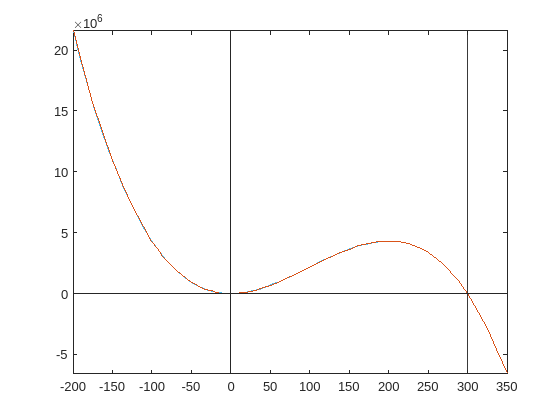

yline(0); hold on;
xline(-0.1470)
xline(-0.1471)
xline(299.99)
fplot(sphere_cap, [-200, 350]); hold off;

**b.  Solve the question with the iterative algorithm shown below**

The below diagram is sourced from the provided coursework, all rights and attributions lie with the University of ...

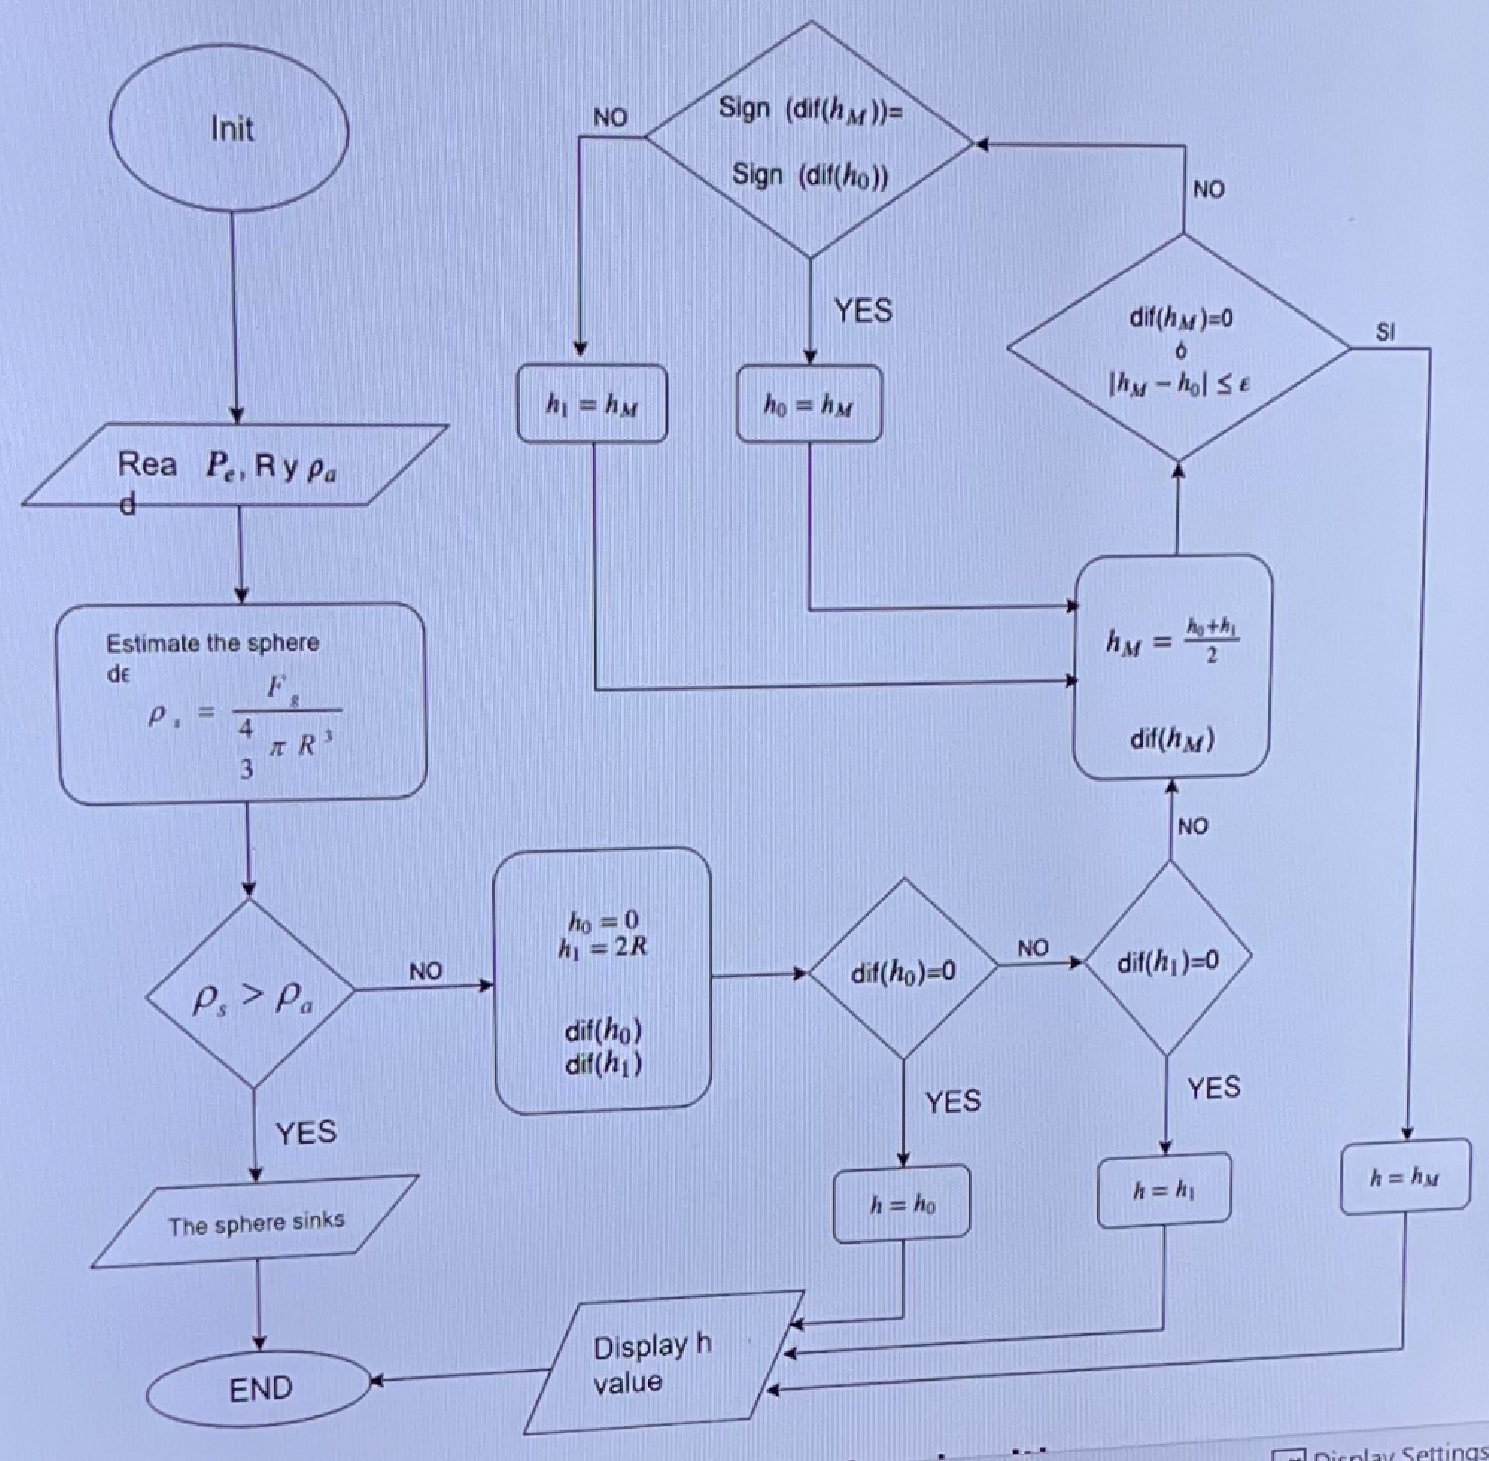

This is an alternative method to analytically determining h, whereby throught the use of a series of decisions forming a 'pipeline' an evaluation of h is determined. 

Note the above diagram makes use of a form of the bisection method (https://en.wikipedia.org/wiki/Root-finding_algorithms) within its inner loop in order to shrink the search space of h over each iteration. 

I have provided a bried summation of psuedo-code that provides an outline to how the above pipeline could be implemented.

```

function sphere_cap_pipeline(R, p_a, F_g, epsilon)

    % Estimate the sphere density compared to the liquid (if it is denser than liquid it will sink)

    p_s = calculate p_s()

    if p_s > p_a:

        The sphere will sink

    else: 

        Continue pipeline to calculate h

        h = find_h(R, p_a, F_g, epsilon)

```

The below function serves to find the value for h, after confirmation that the sphere is not sinking. 

```

function find_h(R, p_a, F_g, epsilon):

    % Initialize the h0 and h1 variables

    h0=0, h1=2R

    % Using the provided equations [1]-[4] at the start of the document. 

    if dif(h0) == 0:

        return h0

    else if dif(h1) == 0:

        return h1

    else:

        return h_internal_loop_calculation(h0, h1, dif, epsilon)

```

The below pseudocode performs the internal loop of the provided diagram

function h_internal_loop_calculation(h0, h1, dif, epsilon):

    % Calculate the initial h_m value

    h_m = (h0 + h1) / 2

    h_m_dif = dif(h_m)

    % Continue while loop, while h_m - h_0 is larger than epsilon, and h_m_dif does not equal zero

    while |`h_m - h0| > epsilon and h_m_dif not equal to zero:`

`        % Update h_m value and its dif per loop to iteratively improve h`

        h_m = (h0 + h1) / 2

                h_m_dif = dif(h_m);

                h0_dif = dif(h0);

                if sign(h_m_dif) == sign(h0_dif):

                    h0 = hm

                else: 

                    h1 = h_m

```

Another alternative is to use an iterative root finding algorithm such as the Newton Raphson algorithm. 

The pseudocode of the Newton Raphson algorithm has been provided below to guide you in creating the algorith. 

Note that the initial value of h_init largely determines which roots will be found, as it provides a starting point for the algorithm.

```

function newtoon raphson(h_init, R, p_a, F_g, epsilon):

    % Create the functions [1]-[4] provided at the start of the documentation. These will be used in the algorithm

    % Initialize h_prev and h_current which will be used in the loop (Initialize h_prev to be slightly different to h_init)

    h_prev = h_init -2   

    h_current = h_init

    % Begin while loop. Exit while loop when |`h_prev - h_current` |  < epsilone

    while |h_prev - h_current| > epsilone:

        % Update the h_prev value

        h_prev = h_current

        % Calculate the derivative of dif, at h_current

        derivative = derivative(dif, h_current)

        % Calculate the next h_value and update it to be h_current

        h_current = h_current - (dif(h_current) / derivative)

```

**Matlab additionally provides multiple built in root finding algorithms including fzero() and solve().**

Below demonstrates their use. 

fzero only returns a single root dependent on the initial value. 

Initial values giving different roots include h_init = [0, 1, 100] each generates a unique root

h_init =1

h_init = 1

h = fzero(sphere_cap, h_init)

h = 0.1471

syms x

sphere_cap_eq = ((p_a / 3) * pi * x^2) * ((3 * R) - x) - F_g == 0

$$sphere\_cap\_eq = -\frac{103\,\pi \,x^{2}\,\left(x-300\right)}{300}-7=0$$

h = solve(sphere_cap_eq, x, 'Real', true) 

$$h = \left(\begin{array}{c} \mathrm{root}\left(103\,\pi \,z^{3}-30900\,\pi \,z^{2}+2100,z,1\right)\\ \mathrm{root}\left(103\,\pi \,z^{3}-30900\,\pi \,z^{2}+2100,z,2\right)\\ \mathrm{root}\left(103\,\pi \,z^{3}-30900\,\pi \,z^{2}+2100,z,3\right) \end{array}\right)$$

## Calculation of Trigonometric Functions

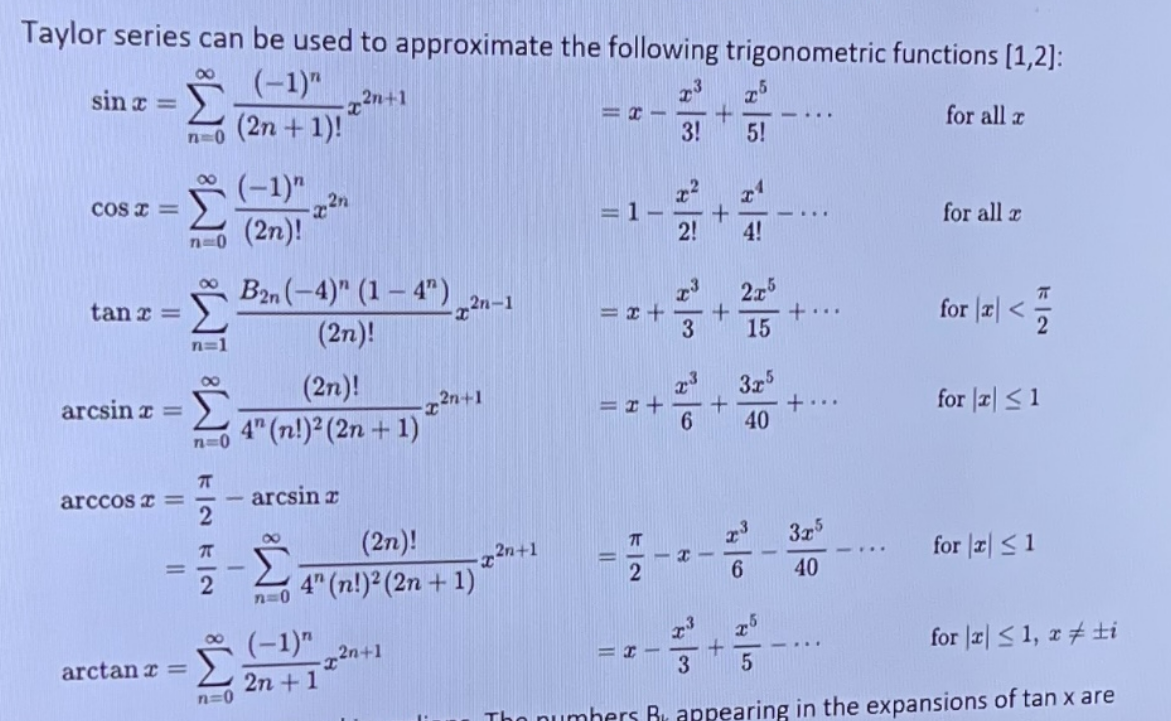

- All angles are expressed in Radians

- The numbers B_k appearing in the expansions of tanx are the Bernoulli numbers. 

- These series approximations and CORDIN are used in computers for finding the value of trigonometric functions. 

**A. Plot the principle branches of sin^(-1) (x), cos^(-1) (x), and tan^(-1) (x).**

Here are two great links explaining the concept of a principle value branch. The below notes are derived from these reousrces:

- [https://youtu.be/cOttZmdk-gk](https://youtu.be/cOttZmdk-gk) 

- [https://www.ck12.org/na/inverse-trigonometric-functions-and-principal-value-branch-1/lesson/Inverse-Trigonometric-Functions-xii-maths/](https://www.ck12.org/na/inverse-trigonometric-functions-and-principal-value-branch-1/lesson/Inverse-Trigonometric-Functions-xii-maths/) 

The range of the inverse trigonometric function is is called the principle value branch. 

Take for example the function sin(x):

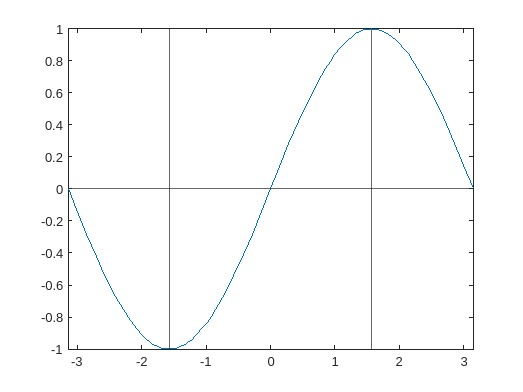

fplot(@(x) sin(x), [-pi, pi]); hold on;
xline(-pi/2)
xline(pi/2);
yline(0); hold off;

The range of sin(x): [-1, 1]. 

In order to create an inverse function, a restriction is required in order to make sin(x) a one-to-one function that allows for the full range of the function. 

The domain of sin(x): [- pi/2, pi/2]. 

Now plotting the inverse function sin^-1(x)

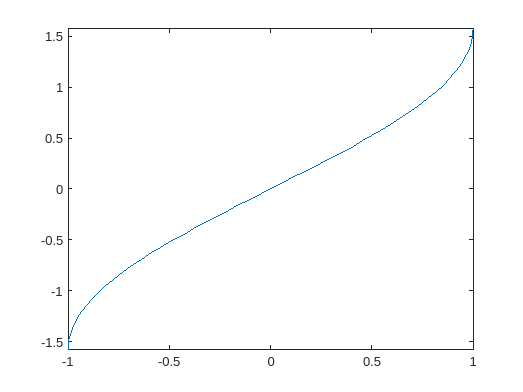

fplot(@(x) asin(x), [-1, 1])

Inverse domain: [-1, 1]

Inverse range: [-pi/2, pi/2]

In the inverse plot above, we can see that the domain of the inverse function is equal to the range of the standard function. Hence the prinicple branch of the inverse of sin(x) is **[-pi/2, pi/2].**

Using the above information we can follow the same procedure for the inverse of both cos(x) and tan(x)

**cos(x):**

Range: [-1, 1]

Domain: [0, pi]

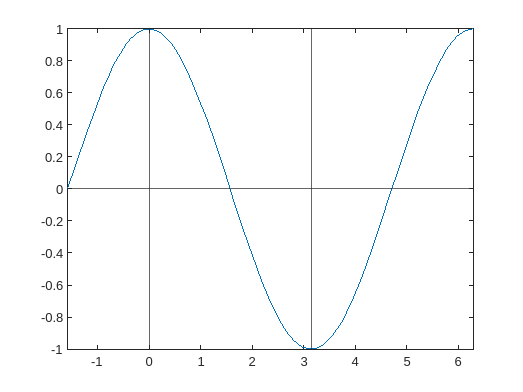

fplot(@(x) cos(x), [-pi/2, 2*pi]); hold on;
xline(0);
xline(pi);
yline(0); hold off;

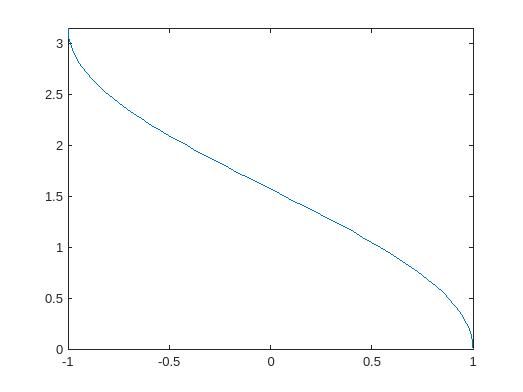

fplot(@(x) acos(x), [-1, 1])

Principle branch of the inverse of cos(x): [0, pi]

**tan(x)**

Range: (-inf, inf)

Domain (-pi/2, pi/2)

The domain boundaries are non-inclusive as they are the asymptotic boundaries of the tan(x) function.

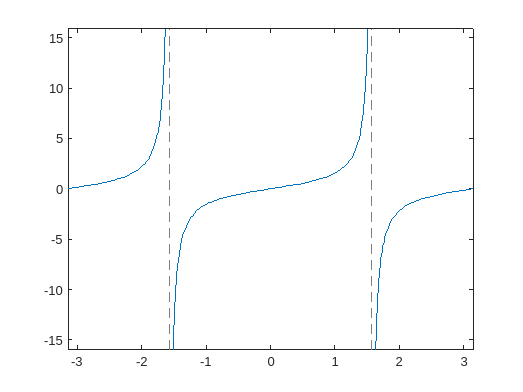

fplot(@(x) tan(x), [-pi, pi])

Principle branch of the inverse of tan(x): (-pi/2, pi/2)

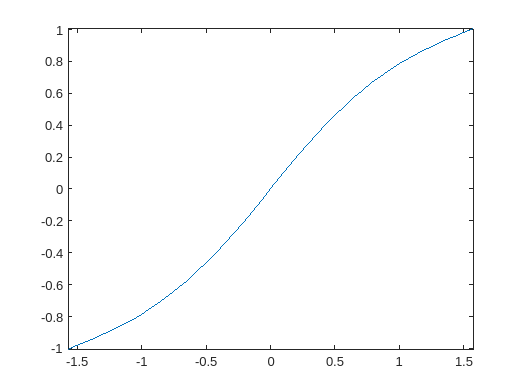

fplot(@(x) atan(x), [-pi/2, pi/2])

**B. Write a matlab function called (trigTaylor) that takes three input arguments (x, numterms, type) and returns the value of the trigonometric functions evaluated at x. The input parameters are:**

- x: Number where is evaluated (for sin, cos, tan). It is an angle in Radians. 

- numterms: Number of terms used for the series approximation.

- type: Select the type of trigonometric function

trigTaylor(pi/4, 20, 'arcsin')

Arcsin


value = 0.7854

value = 0.8661

value = 0.8886

value = 0.8968

value = 0.9002

value = 0.9018

value = 0.9026

value = 0.9029

value = 0.9031

value = 0.9032

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

value = 0.9033

ans = 0.9033

asin(pi/4)

ans = 0.9033

## Functions (1)

Question 1C. The Newton Raphson

% Function performs the newton raphson iterative algorithm and returns the
% value for h

function [h_current] = newton_raphson(h_init, R, p_a, F_g, epsilon)
    % Create functions allowing dif calculation
    syms h
    vol_h = ((1/3) * pi * h^2) * ((3 * R) - h);
    boyancy_f = p_a * vol_h;
    dif = boyancy_f - F_g;
    
    % Initialize h_prev and h_current for use in the loop
    h_prev = h_init + 5;
    h_current = h_init;

    % Iteratively solve until finding h. 
    % Stopping conditions are when h0 and h_next are similar to each other
    % (within epsilon)
    while abs(h_prev - h_current) > epsilon
        % Update the prev h value to the h_current
        h_prev = h_current;

        % Calculate the derivative of h_current 
        derivative = diff(dif, h);
        h_current_derivative = double(subs(derivative,h_current));

        % Update the value of h_current using the Newton-Raphson equation
        h_current = h_current - (double(subs(dif, h_current)) / h_current_derivative)
    end
end

## Functions (2)

% Function 
function [value] = trigTaylor(x, numterms, type)
    switch type
        case 'sin'
            disp('Sin')
            value = sin_taylor(x, numterms);
        case 'cos'
            disp('Cos')
            value = cos_taylor(x, numterms);
        case 'tan'
            disp('Tan')
            value = tan_taylor(x, numterms);
        case 'arcsin'
            disp('Arcsin')
            value = arcsin_taylor(x, numterms);
        case 'arccos'
            disp('Arccos')
            value = 0;
        case 'arctan'
            disp('Arctan')
            value = 0;
    end
end

function [value] = sin_taylor(x, n)
    value = 0;
    for i = 0:n
        value = value + (((-1)^i) / (factorial((2 * i) + 1))) * x^((2 * i) + 1);
    end
end

function [value] = cos_taylor(x, n)
    value = 0;
    for i = 0:n
        value = value + (((-1)^i) / (factorial(2 * i))) * x^(2 * i);
    end
end

function [value] = tan_taylor(x, n)
    value = 0;
    for i = 1:n
        value = value + (((bernoulli(2, x)) * ((-4) ^ i) * (1 - (4 ^ i))) / (factorial(2 * i))) * x ^ ((2 * i) - 1)
    end
end

function [value] = arcsin_taylor(x, n)
    value = 0;
    for i = 0:n
        value = value + ((factorial(2 * i)) / ((4 ^ i) * ((factorial(i)) ^ 2) * ((2 * i) + 1))) * x ^ ((2 * i) + 1);
    end
end